# Cross-validation

Cross-validation is performed by removing one radar at the time and estimating bird density at the exact same location (and time). Comparing the estimation (and uncertainty estimated) to the true value allows to assess the model. 

## 1. Loading

clear all; load('../1-Cleaning/data/dc_corr.mat'); 
load('../2-Inference/data/Density_inference_wind_temp.mat');
load coastlines; addpath('functions\')
dclat = [dc.lat]'; dclon = [dc.lon]'; dcname={dc.name};
clear dc

## 2. Amplitude

Compute the full covariance matrix

Dtime=squareform(pdist(ampli.T(~ampli.isnan)));
Ddist=squareform(pdist([dclat(ampli.R(~ampli.isnan)) dclon(ampli.R(~ampli.isnan))],@lldistkm));

C=nan(size(Ddist,1)*3);
for i_v1=1:size(ampli.A,3)
    for i_v2=1:size(ampli.A,3)
        C( (1:size(Ddist,1))+size(Ddist,1)*(i_v1-1) , (1:size(Ddist,1))+size(Ddist,1)*(i_v2-1) ) = ampli.cov.C{i_v1,i_v2}(Ddist,Dtime);
    end
end

ccampli.i_r=ampli.R(~ampli.isnan);

ccampli.An_est_1=nan(size(ampli.An,1),1);
ccampli.An_est_2=nan(size(ampli.An,1),1);
ccampli.An_est_3=nan(size(ampli.An,1),1);
ccampli.An_est_4=nan(size(ampli.An,1),1);
ccampli.An_sig=nan(size(ampli.An,1),1);

For each radar, ignore all its data

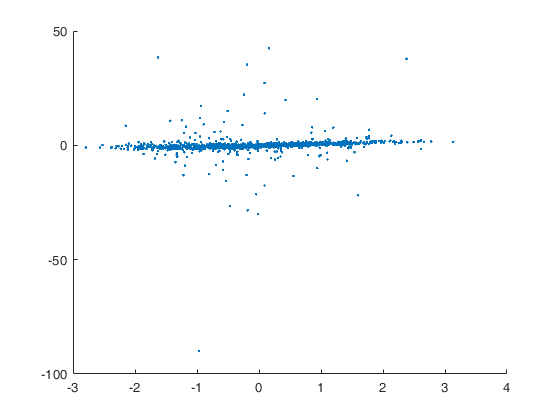

for i_d=1:numel(ampli.r)

    sim=ccampli.i_r==i_d;
    
    % Remove also radars within 100km
    %sim(Dist_km_sf(i,:)<100)=false;
    
    id = find([~sim; true(size(Ddist,1),1) ; true(size(Ddist,1),1)]);
    Cab =C(id, [sim; false(size(Ddist,1)*2,1)]);
    id2=id(any(Cab>0.01,2));
    lambda = C(id2,id2) \  C(id2, [sim; false(size(Ddist,1)*2,1)]);
    ccampli.An_est_1(sim) =  lambda' * ampli.An(id2);
    
%     id = [~sim; true(size(Ddist,1),1) ; false(size(Ddist,1),1)];
%     lambda = C(id, id) \  C(id, [sim; false(size(Ddist,1)*2,1)]);
%     ccampli.An_est_2(sim) =  lambda' * ampli.An(id);
%     
%     id = [~sim; false(size(Ddist,1),1) ; true(size(Ddist,1),1)];
%     lambda = C(id, id) \  C(id, [sim; false(size(Ddist,1)*2,1)]);
%     ccampli.An_est_3(sim) =  lambda' * ampli.An(id);
%     
    id = [~sim; false(size(Ddist,1),1) ; false(size(Ddist,1),1)];
    lambda = C(id, id) \  C(id, [sim; false(size(Ddist,1)*2,1)]);
    ccampli.An_est_4(sim) =  lambda' * ampli.An(id);
    
    % ccampli.An_sig(sim) = sqrt(sum(ampli.cov.parm(1,1,1:3)) - sum(lambda.*C([~sim; true(size(Ddist,1)*2,1)], [sim; false(size(Ddist,1)*2,1)])) );
    
end

figure; hold on
plot(ampli.An(:,1),ccampli.An_est_1,'.')
plot(ampli.An(:,1),ccampli.An_est_2,'.')
plot(ampli.An(:,1),ccampli.An_est_3,'.')

mean((ccampli.An_est_1-ampli.An(:,1)).^2)

ans = 18.8311

mean((ccampli.An_est_2-ampli.An(:,1)).^2)

ans = NaN

mean((ccampli.An_est_3-ampli.An(:,1)).^2)

ans = NaN

mean((ccampli.An_est_4-ampli.An(:,1)).^2)

ans = 0.4264

Add the trend back

ccampli.A_est=nan(size(ampli.isnan)); 
ccampli.A_sig=nan(size(ampli.isnan));
ccampli.A_est(~ampli.isnan) = ccampli.An_est*ampli.w(3,1)+dclat(ampli.R(~ampli.isnan))*ampli.w(2,1)+ampli.w(1,1);

Reference to non-existent field 'An_est'.

ccampli.A_sig(~ampli.isnan) = ccampli.An_sig;

Compute the normalized error of estimation


$$\frac{{Z^p }^* -Z^p }{\sigma_{{Z^p }^* } }$$


ccampli.nee = (ccampli.A_est-ampli.A(:,:,1)) ./ ccampli.A_sig;

figure('position',[0 0 1000 400]); histogram(ccampli.nee(:),'Normalization','pdf');
hold on; plot(-4:.1:4,normpdf(-4:.1:4),'linewidth',2)
legend(['Normalized error of kriging with mean: ' num2str(nanmean(ccampli.nee(:))) ' and variance: ' num2str(nanvar(ccampli.nee(:)))]);

Normalized error per radar

ccampli_nee_avg=splitapply(@mean,ccampli.nee(~ampli.isnan),ccampli.i_r);
ccampli_nee_var=splitapply(@var,ccampli.nee(~ampli.isnan),ccampli.i_r);

Illustrattion of the normalized error of estimation

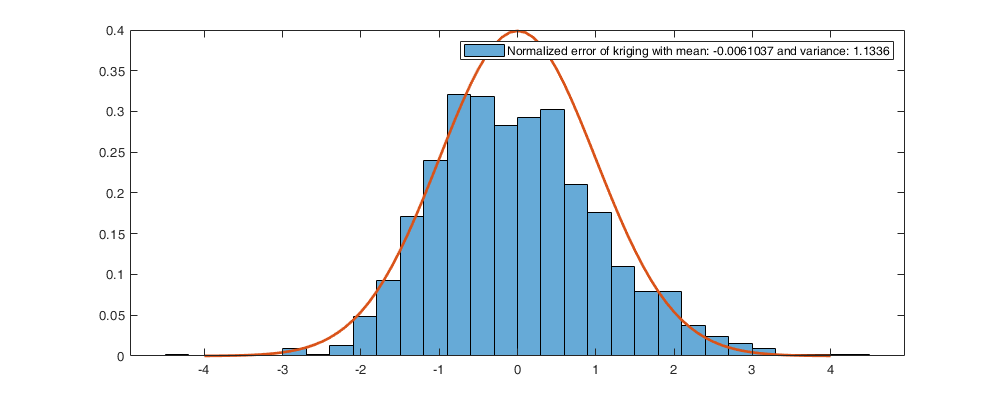

figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,ccampli_nee_avg,'filled','MarkerEdgeColor','k'); title('Mean normalized error of kriging'); colorbar;

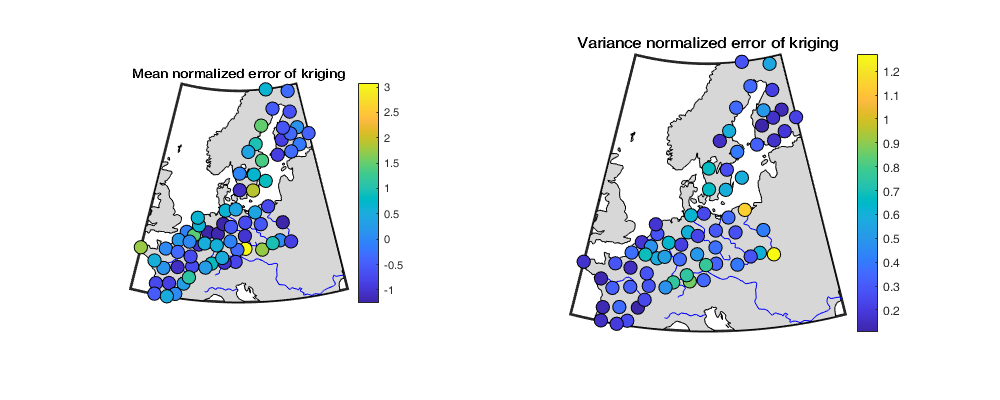

subplot(1,2,2); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,ccampli_nee_var,'filled','MarkerEdgeColor','k'); title('Variance normalized error of kriging'); colorbar;

## 3 Residual

Build the covariance function from the distance

Ddist_sm = squareform(pdist([dclat dclon], @lldistkm));

D=table();
for i_t=1:numel(ampli.t)
    id = find(data.day==i_t);
    d = table();
    d.Ddist = reshape(Ddist_sm(data.radar(id),data.radar(id)),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),1);
    d.Did2 = repelem(id,numel(id));
    D=[D ; d];
end

C_res = sparse(D.Did1,D.Did2, res.cov.C(D.Ddist, D.Dtime));

Estimate the value removing all values of the radar.

ccres.Rn_est=nan(size(res.Rn));
ccres.Rn_sig=nan(size(res.Rn));

for i_t=1:numel(ampli.t)
    id_t= find(i_t==data.day);
    for i_r=1:numel(ampli.r)
        
        id_r = i_r==data.radar(id_t);
    
        Lambda = C_res(id_t(~id_r),id_t(~id_r))\C_res(id_t(~id_r),id_t(id_r));
        
        ccres.Rn_est(id_t(id_r)) = Lambda' * res.Rn(id_t(~id_r));
        ccres.Rn_sig(id_t(id_r)) = sqrt(sum(res.cov.parm(1:3)) - sum(Lambda.*C_res(id_t(~id_r),id_t(id_r))));

    end
end

Add the trend back

ccres.R_est = ccres.Rn_est .* sqrt(bsxfun(@power,data.NNT,0:res.bpo)*res.b) + bsxfun(@power,data.NNT,0:res.apo)*res.a;
ccres.R_sig = sqrt(ccres.Rn_sig.^2 .* (bsxfun(@power,data.NNT,0:res.bpo)*res.b));

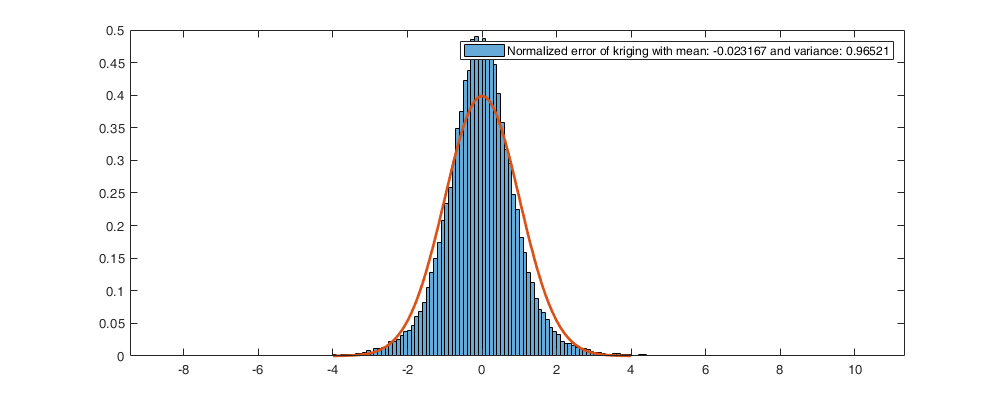

ccres.nee = (ccres.R_est-res.R) ./ ccres.R_sig;

figure('position',[0 0 1000 400]); histogram(ccres.nee,'Normalization','pdf');
hold on; plot(-4:.1:4,normpdf(-4:.1:4),'linewidth',2)
legend(['Normalized error of kriging with mean: ' num2str(mean(ccres.nee)) ' and variance: ' num2str(var(ccres.nee))]);

Normalized error per radar

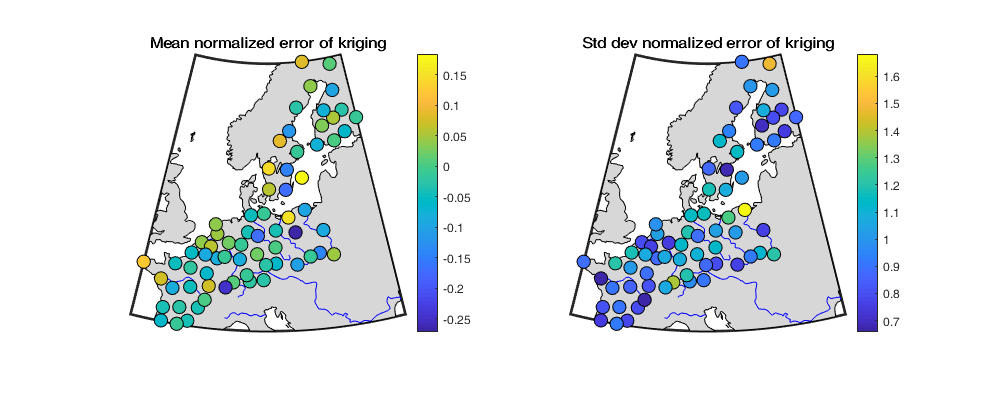

ccres_nee_avg=splitapply(@mean,ccres.nee,data.radar);
ccres_nee_std=splitapply(@std,ccres.nee,data.radar);


figure('position',[0 0 1000 400]);  
subplot(1,2,1); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,ccres_nee_avg,'filled','MarkerEdgeColor','k'); title('Mean normalized error of kriging'); colorbar;
subplot(1,2,2); hold on; h=worldmap([min(dclat) max(dclat)], [min(dclon) max(dclon)]);  
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
scatterm(dclat,dclon,100,ccres_nee_std,'filled','MarkerEdgeColor','k'); title('Std dev normalized error of kriging'); colorbar;

## 4. Assemble the estimation

cc.denst_est = ccampli.A_est(data.dayradar) + ccres.R_est;
cc.denst_sig = sqrt(ccampli.A_sig(data.dayradar).^2 + ccres.R_sig.^2);

Transform back to the original space. Value below zero cannot be converted. 

if any(cc.denst_est<0)
    disp(['WARNING: Remove ' num2str(sum(cc.denst_est<0)) ' value(s) because <0'])
    cc.denst_est(cc.denst_est<0)=nan;
end
cc.dens_est = (cc.denst_est).^(1/pow_a);

## 5. Performance assessment

Visual figure

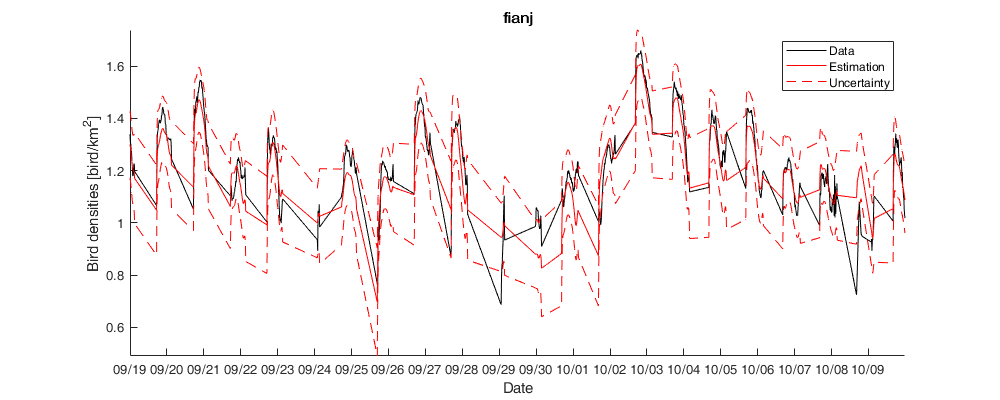

i_d=22;
figure('position',[0 0 1000 400]); hold on;
id=data.radar==i_d;
plot(data.time(id),data.denst(id),'k');
plot(data.time(id),cc.denst_est(id),'r')
plot(data.time(id),cc.denst_est(id)-cc.denst_sig(id),'--r')
plot(data.time(id),cc.denst_est(id)+cc.denst_sig(id),'--r');
datetick('x');axis tight; xlabel('Date'); ylabel('Bird densities [bird/km^2]'); legend('Data','Estimation','Uncertainty'); title(dcname(i_d))

Root-mean-squared error

%cc.rmse_denst = sqrt(nanmean( (cc.denst_est-data.denst ).^2 ));
cc.rmse_dens = sqrt(nanmean( (cc.dens_est-data.dens ).^2 ));
disp(['RMSE: ' num2str(cc.rmse_dens) ' (bird/km^2)'])

RMSE: 17.6653 (bird/km^2)


Normalized error of estimation

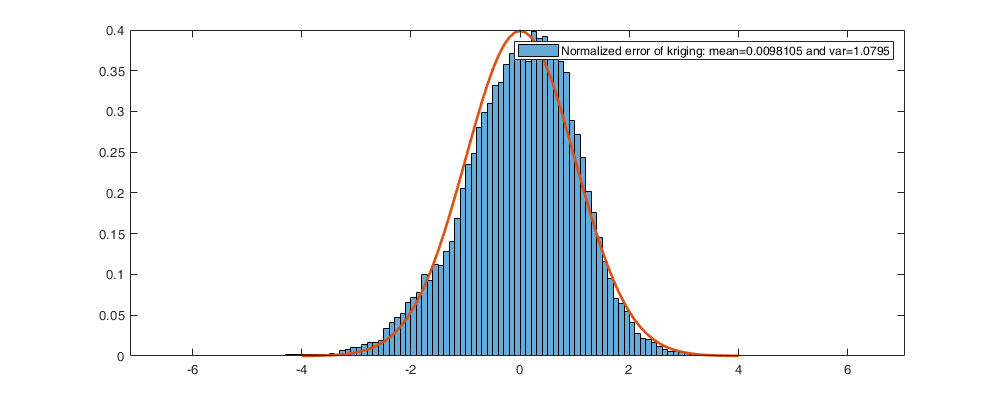

cc.nee = (data.denst-cc.denst_est)./cc.denst_sig;
figure('position',[0 0 1000 400]); histogram( cc.nee ,'Normalization','pdf');
hold on; plot(-4:.1:4,normpdf(-4:.1:4),'linewidth',2)
legend(['Normalized error of kriging: mean=' num2str(nanmean(cc.nee)) ' and var=' num2str(nanvar(cc.nee))]);

QQ-plot

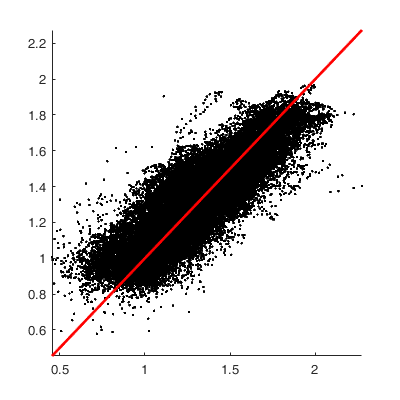

figure('position',[0 0 400 400]); hold on
plot(data.denst,cc.denst_est,'.k'); 
% coef=data.dens(~isnan(cc.dens_est)) \ cc.dens_est(~isnan(cc.dens_est));
plot([min(data.denst) max(data.denst)],[min(data.denst) max(data.denst)],'-r','LineWidth',2);
axis([min(data.denst) max(data.denst) min(data.denst) max(data.denst)])

## 7. Save

save('data/Density_crossValidation.mat','cc','ccampli','ccres')